# CAPÍTULO 12 - CARGA DINÁMICA DE SISTEMAS DE BARRAS

Estudia el máximo de una carga de impacto o la acción centrífuga sobre una barra radial en rotación.

Dimensión: impacto axial, voladizo o estructura espacial mediante su flexibilidad. El modelo energético obtiene máximos; no calcula una animación temporal del impacto.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

modo="impacto" o "rotacion". estructura="axial", "voladizo", "marco_3d" o "rigidez_dada" determina la rigidez estática equivalente. masa está en kg, altura en m y velocidadInicial en m/s. En rotación, radioInicio es la distancia del empotramiento al eje de giro y omega está en rad/s.

modo="impacto";
estructura="axial";
L=2; E=210e9; F=400e-6; I=8e-6; c=.08;
masa=10; altura=.02; velocidadInicial=0; gravedad=9.81;
rigidezDada=1e6; limiteElastico=250e6;
densidad=7850; radioInicio=.2; omega=50;
nodosImpacto=[0 0 0;0 1 0;2 1 0]; barrasImpacto=[1 2;2 3];
apoyosImpacto=[1 0 0 0 0 0 0]; nodoImpacto=3; direccionImpacto=[0 0 -1];
Gimpacto=80e9; IyImpacto=8e-6; IzImpacto=8e-6; Jimpacto=16e-6;

## 2. Balance de energía o fuerzas de inercia


$$\frac12k\delta_{\max}^2=\frac12m v_{impacto}^2+mg\delta_{\max},\qquad v_{impacto}^2=v_0^2+2gh$$



$$k_{axial}=EF/L,\quad k_{voladizo}=3EI/L^3,\qquad q(x)=\rho F\omega^2(r_0+x)$$


assert(all([L E F masa gravedad limiteElastico]>0) && altura>=0 && velocidadInicial>=0,'Datos invalidos.');
if modo=="impacto"
    if estructura=="axial", k=E*F/L;
    elseif estructura=="voladizo", k=3*E*I/L^3;
    elseif estructura=="marco_3d"
        assert(norm(direccionImpacto)>0,'Direccion de impacto nula.');
        direccionImpacto=direccionImpacto/norm(direccionImpacto);
        datosImpacto=struct('nodos',nodosImpacto,'barras',barrasImpacto,'E',E,'G',Gimpacto,'F',F, ...
            'Iy',IyImpacto,'Iz',IzImpacto,'J',Jimpacto,'apoyos',apoyosImpacto, ...
            'cargas',[nodoImpacto direccionImpacto 0 0 0]);
        unitario=rm_marco3d(datosImpacto);
        flexibilidad=dot(direccionImpacto,unitario.u(nodoImpacto,1:3));
        assert(flexibilidad>0,'La direccion de impacto esta impedida.');k=1/flexibilidad;
    else, assert(estructura=="rigidez_dada" && rigidezDada>0,'Rigidez invalida.'); k=rigidezDada; end
    velocidadImpacto=sqrt(velocidadInicial^2+2*gravedad*altura);
    deltaEstatica=masa*gravedad/k;
    deltaMax=(masa*gravedad+sqrt((masa*gravedad)^2+k*masa*velocidadImpacto^2))/k;
    fuerzaMax=k*deltaMax; factorDinamico=deltaMax/deltaEstatica;
    if estructura=="axial", sigmaMax=fuerzaMax/F;
    elseif estructura=="voladizo", sigmaMax=fuerzaMax*L*c/I;
    else, sigmaMax=NaN; end
    residuoEnergia=.5*k*deltaMax^2-.5*masa*velocidadImpacto^2-masa*gravedad*deltaMax;
    resultado=struct('rigidez',k,'deltaMax',deltaMax,'fuerzaMax',fuerzaMax, ...
        'factorDinamico',factorDinamico,'sigmaMax',sigmaMax,'residuoEnergia',residuoEnergia);
    disp(resultado);
else
    assert(modo=="rotacion" && densidad>0 && radioInicio>=0 && omega>=0,'Datos de giro invalidos.');
    q0=densidad*F*omega^2*radioInicio; q1=densidad*F*omega^2*(radioInicio+L);
    datos=struct('x',[0 L],'E',E,'F',F,'distribuidas',[0 L q0 q1],'apoyos',[0 0]);
    resultado=rm_axial(datos);
    disp(resultado.extremos);
end

           rigidez: 42000000
          deltaMax: 3.0801e-04
         fuerzaMax: 1.2936e+04
    factorDinamico: 131.8678
          sigmaMax: 3.2341e+07
    residuoEnergia: 3.5735e-16



## 3. Representación del máximo

En impacto, fuerza máxima y desplazamiento máximo se refieren al instante de máxima deformación del modelo energético. En una rigidez dada no se deduce tensión sin un modelo adicional de la estructura.

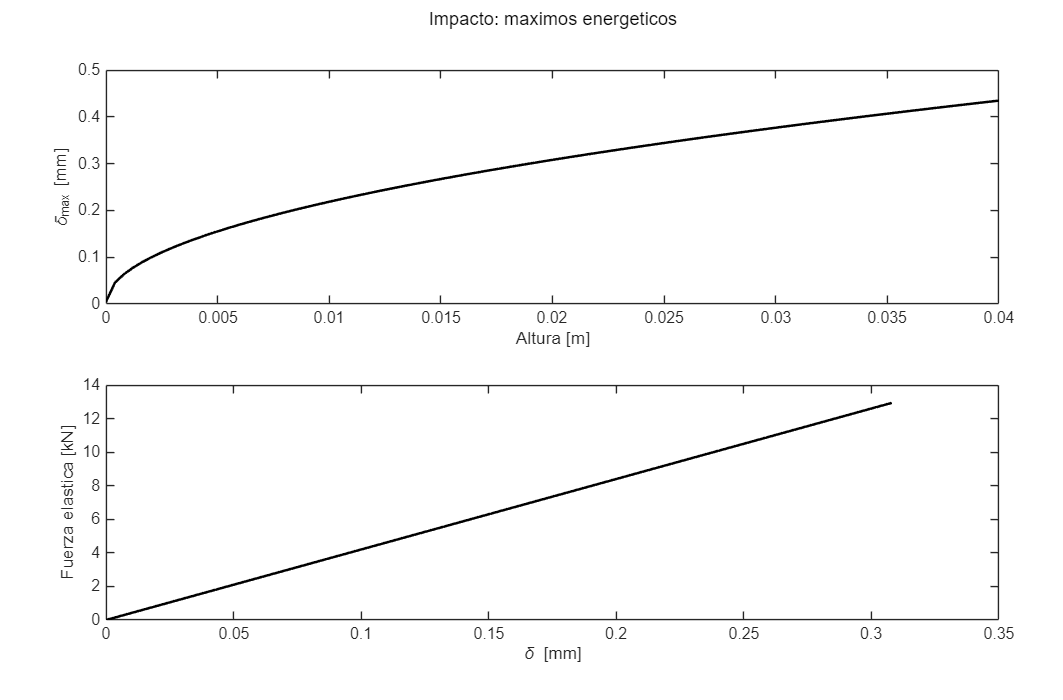

if modo=="impacto"
    [figura,ejes]=rm_figura(2,'Impacto: maximos energeticos');
    hh=linspace(0,max(.01,2*altura),101);
    dd=(masa*gravedad+sqrt((masa*gravedad)^2+k*masa*(velocidadInicial^2+2*gravedad*hh)))/k;
    plot(ejes(1),hh,dd*1000,'k-','LineWidth',1.5); xlabel(ejes(1),'Altura [m]'); ylabel(ejes(1),'\delta_{max} [mm]');
    uu=linspace(0,deltaMax,101); plot(ejes(2),uu*1000,k*uu/1000,'k-','LineWidth',1.5);
    xlabel(ejes(2),'\delta [mm]'); ylabel(ejes(2),'Fuerza elastica [kN]');
else
    t=resultado.tramos(1); xx=linspace(0,L,151);
    [figura,ejes]=rm_figura(3,'Barra radial en rotacion');
    rm_curva(ejes(1),xx,polyval(t.N,xx)/1000,'N [kN]');
    rm_curva(ejes(2),xx,polyval(t.sigma,xx)/1e6,'\sigma [MPa]');
    rm_curva(ejes(3),xx,polyval(t.delta,xx)*1000,'\delta [mm]'); xlabel(ejes(3),'x [m]');
end

En marco_3d, una fuerza unitaria en nodoImpacto y direccionImpacto determina la flexibilidad. Se supone masa estructural despreciable. Se dibuja la deformada al máximo; para verificar resistencia introduce sus esfuerzos en el capítulo 9.

if modo=="impacto" && estructura=="marco_3d"
    datosImpacto.cargas=[nodoImpacto fuerzaMax*direccionImpacto 0 0 0];
    marcoImpacto=rm_marco3d(datosImpacto);
    figuras=rm_graficar_marco3d(marcoImpacto,"locales",false);
end

## Funciones utilizadas

sqrt: calcula una raíz positiva. Aquí elige el máximo de deformación que satisface energía.

rm_axial: resuelve cargas axiales distribuidas. Aquí integra la carga centrífuga lineal.

NaN: representa un dato no determinado. Aquí indica que una rigidez dada por sí sola no permite obtener tensión.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Impacto sobre una estructura lineal sin amortiguamiento y con masa estructural despreciable frente al impactante; o barra radial prismática a velocidad angular constante. Se calcula el máximo energético o equilibrio de inercia, no una historia temporal de ondas o vibraciones.

Conexión con lo anterior: El impacto usa la flexibilidad estática de los capítulos 1, 5 o 7. La rotación reutiliza el equilibrio axial del capítulo 1.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 12: calculo completado.');

Capitulo 12: calculo completado.
